clear;
close all;
axlabels = {'1L2/3e','1L2/3i','1L4e','1L4i','1L5e','1L5i','1L6e','1L6i', ...
    '2L2/3e','2L2/3i','2L4e','2L4i','2L5e','2L5i','2L6e','2L6i'};
pop = 5;
popEI = 3;
sz = 15;

## Delta_i: all pathway raw data

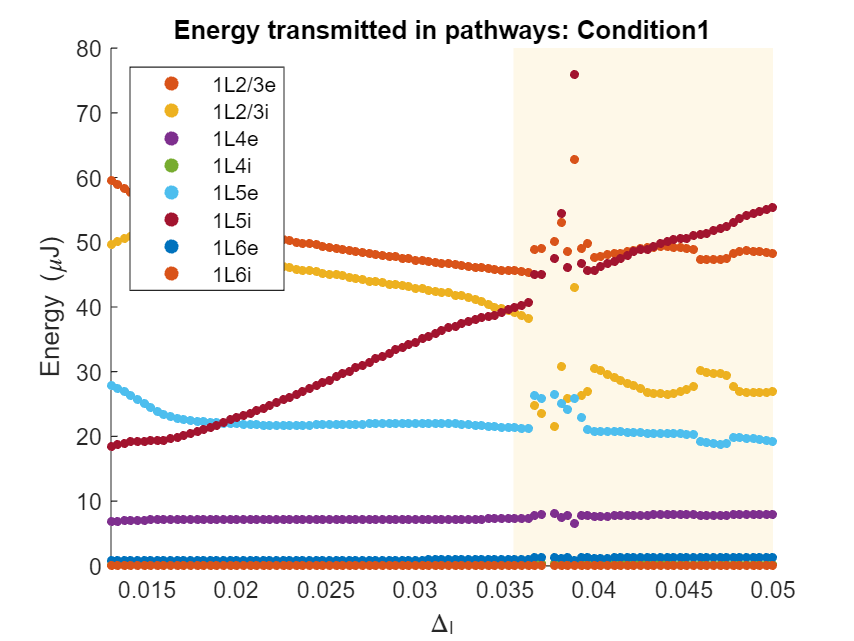

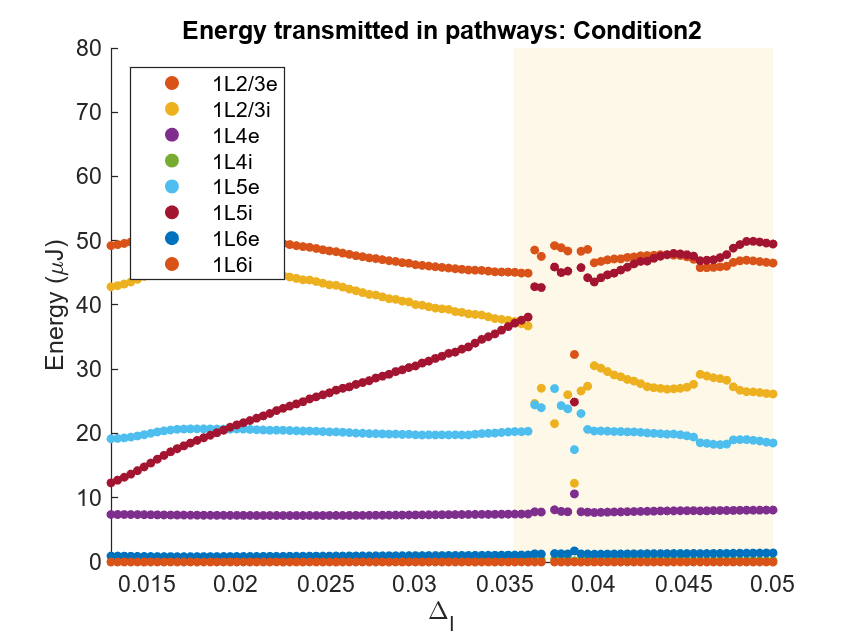

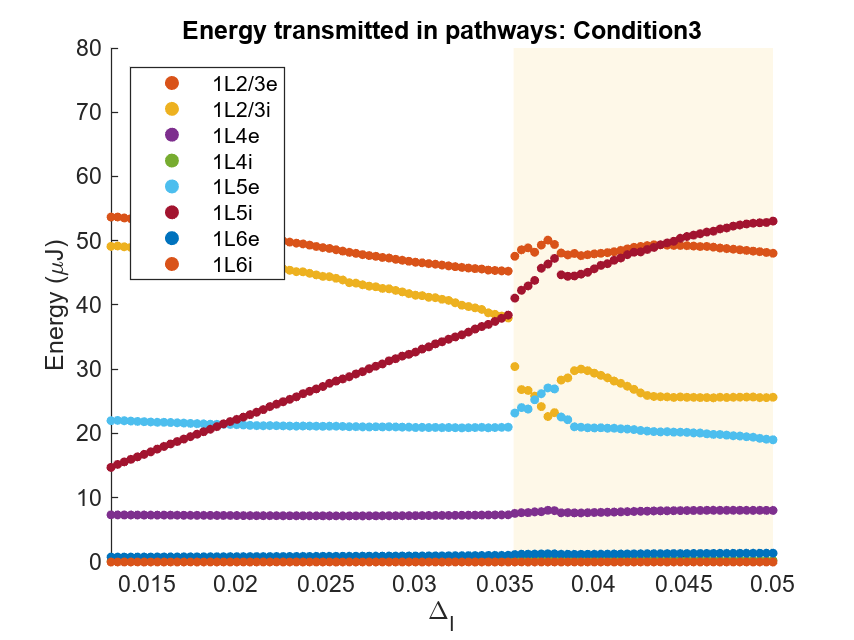

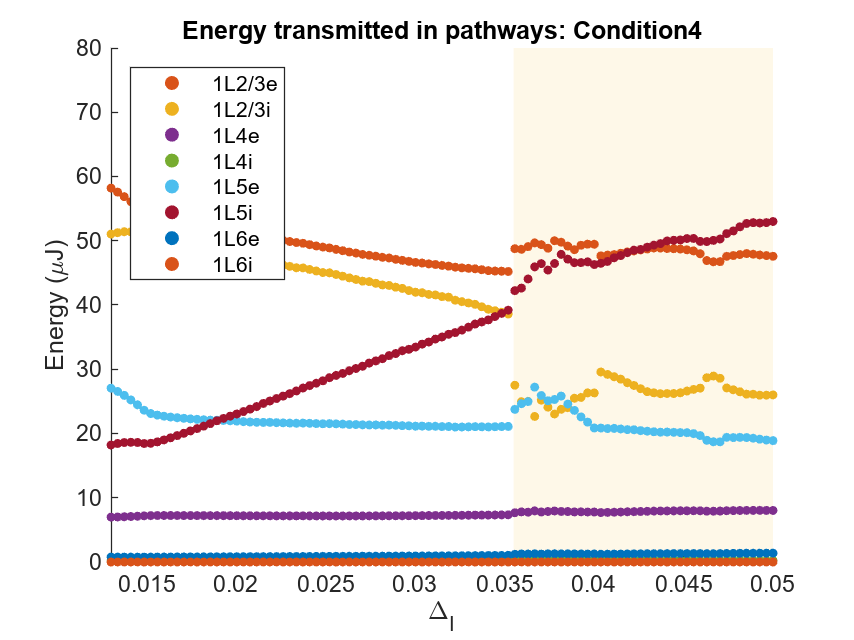

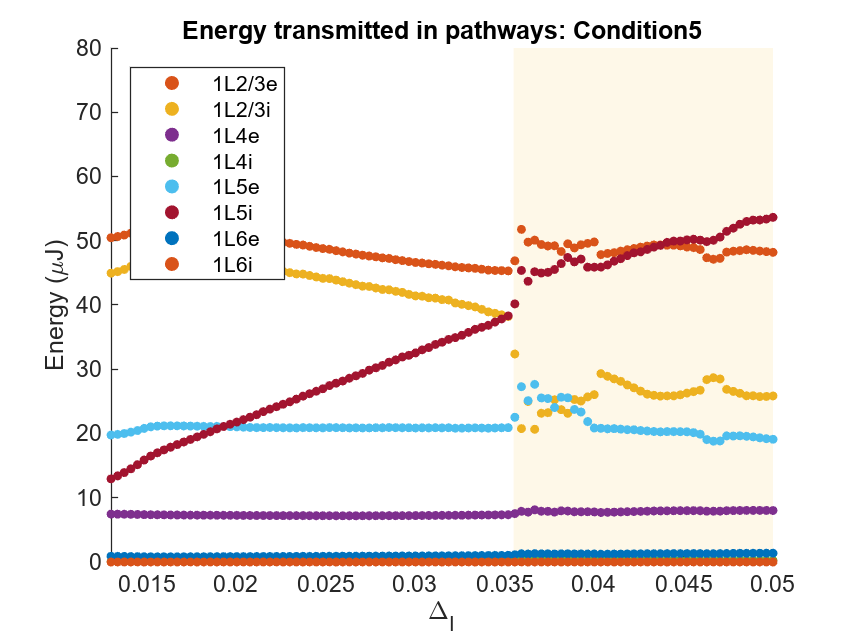

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
lowY = 0; highY = 80; % 80
x = linspace(startX,endX,size(PET,1));

for cond = 1:5
figure();
hold on;
recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

% recX = [0.036 0.05 0.05 0.036];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);

s = zeros(8,1);
for i = 1:8
    y = PET(:,pop,i,cond);
    s(i) = scatter(x,y,sz,'filled','LineWidth',2);
    hold on;
end

legend(s,axlabels(1:8),'Location','northwest');
xlabel("\Delta_{I}");
ylabel("Energy (\muJ)");
title("Energy transmitted in pathways: Condition" + num2str(cond));
axis([startX endX lowY highY]);
end

## Delta_i: sum all excitatory or inhibitory effect

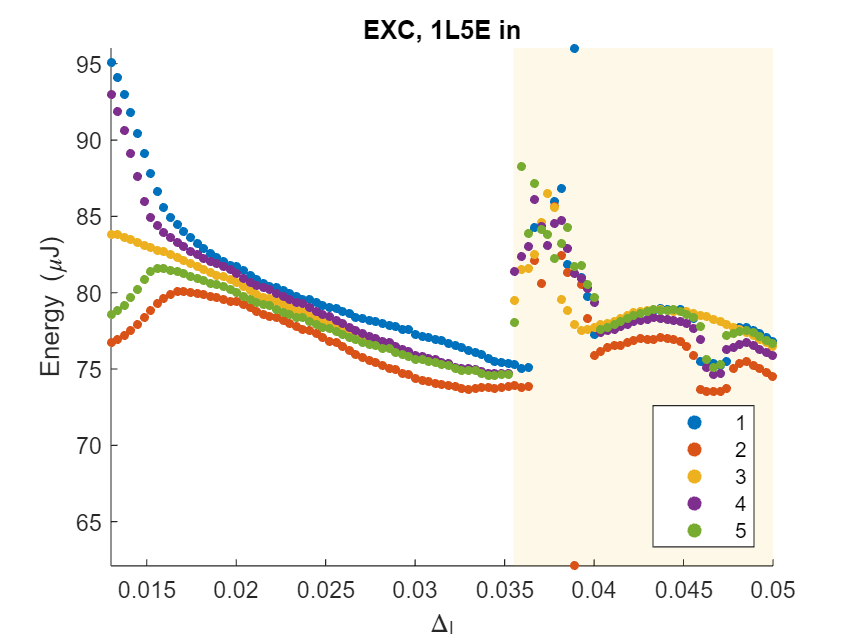

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

x = linspace(startX,endX,size(PET,1));
% EXC (1L5E in)
figure();
hold on

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

s = zeros(5,1);
    s(1) = scatter(x,exc(:,1),sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,exc(:,2),sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,exc(:,3),sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,exc(:,4),sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,exc(:,5),sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"],'Location','southeast');
xlabel("\Delta_{I}");
ylabel("Energy (\muJ)");
title("EXC, 1L5E in");

axis([startX endX min(min(exc)) max(max(exc))]);

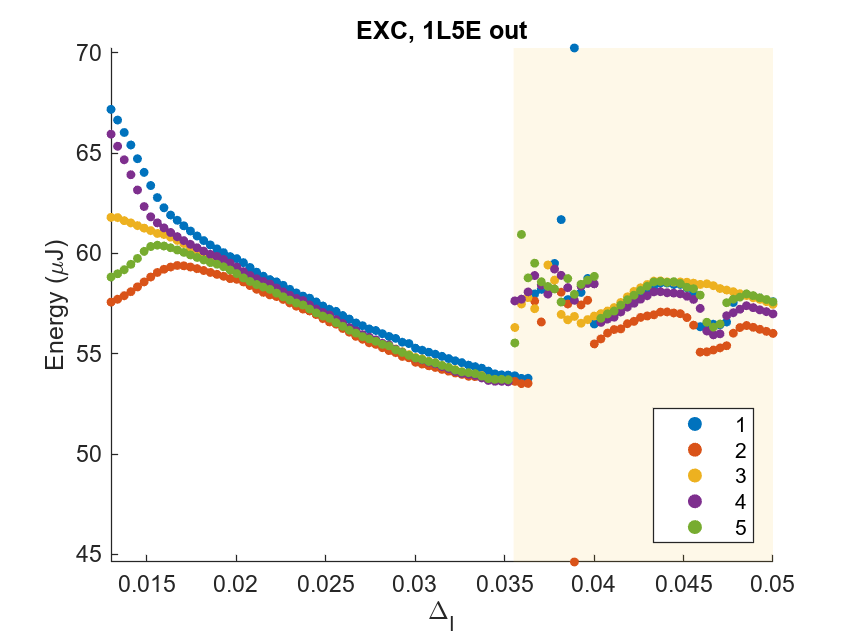


% EXC (1L5E out)
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); % + squeeze(PET(:,pop,7,:));
figure();
hold on

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

s = zeros(5,1);
    s(1) = scatter(x,exc(:,1),sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,exc(:,2),sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,exc(:,3),sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,exc(:,4),sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,exc(:,5),sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"],'Location','southeast');
xlabel("\Delta_{I}");
ylabel("Energy (\muJ)");
title("EXC, 1L5E out");

axis([startX endX min(min(exc)) max(max(exc))]);

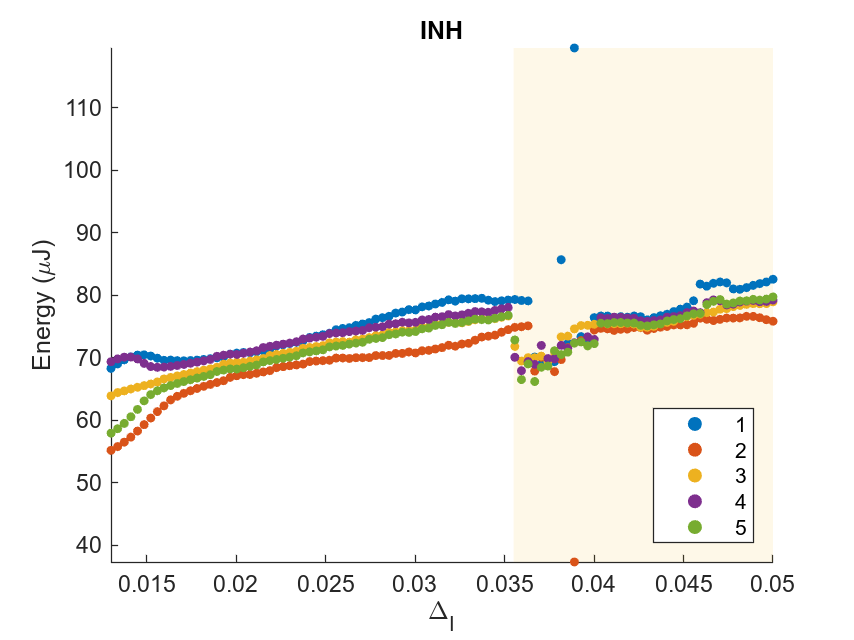


% INH
figure();
hold on

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

s = zeros(5,1);
    s(1) = scatter(x,inh(:,1),sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,inh(:,2),sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,inh(:,3),sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,inh(:,4),sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,inh(:,5),sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"],'Location','southeast');
xlabel("\Delta_{I}");
ylabel("Energy (\muJ)");
title("INH");

axis([startX endX min(min(inh)) max(max(inh))]);

## Delta_i: E-I by cond

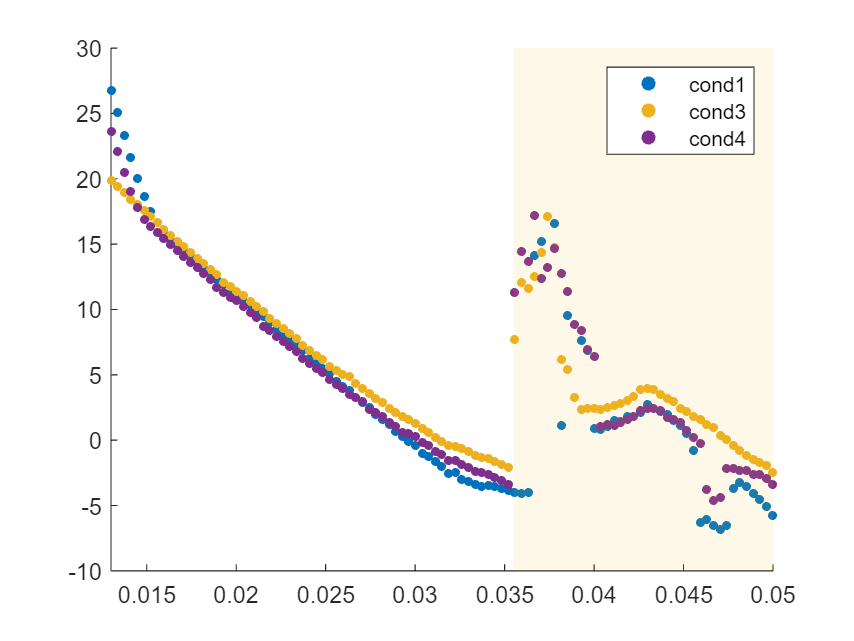

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

x = linspace(startX,endX,size(PET,1));

EI1 = exc(:,1) - inh(:,1);
EI3 = exc(:,3) - inh(:,3);
EI4 = exc(:,4) - inh(:,4);

lowY = -10; highY = 30;
figure();

s1 = scatter(x, EI1, sz, 'filled', 'MarkerFaceColor', '#0072BD');
hold on
s2 = scatter(x, EI3, sz, 'filled', 'MarkerFaceColor', '#EDB120');
s3 = scatter(x, EI4, sz, 'filled', 'MarkerFaceColor', '#7E2F8E');

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

legend([s1 s2 s3],["cond1", "cond3", "cond4"]);
axis([startX endX lowY highY]);

## Delta_i: each E and I by conds

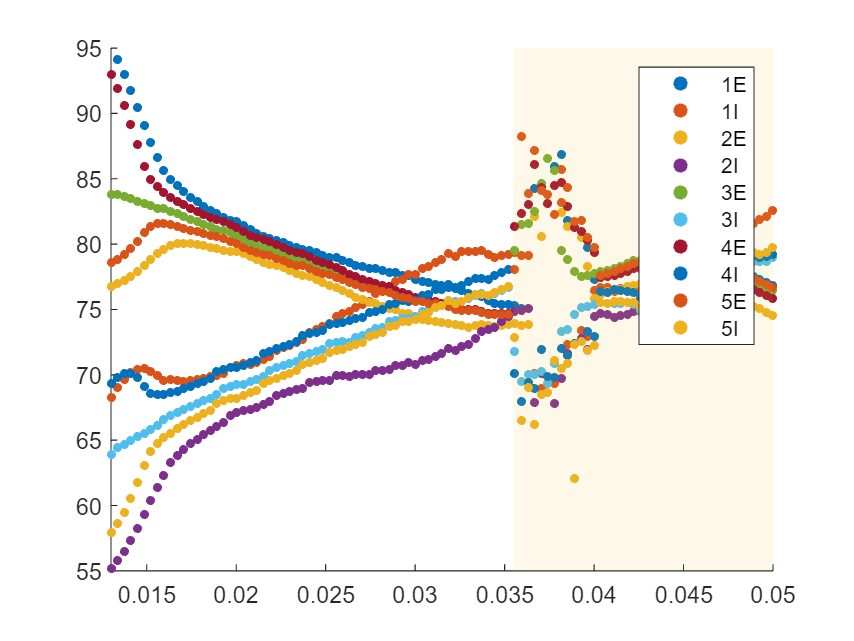

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));

x = linspace(startX,endX,size(PET,1));

figure();
lowY = 55; highY = 95;
s = zeros(10,1);
for i = 1:5
    s(2*i-1) = scatter(x, exc(:,i), sz, 'filled');
    hold on
    s(2*i) = scatter(x, inh(:,i), sz, 'filled');
end

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

labels = {'1E', '1I', '2E', '2I', '3E', '3I', '4E', '4I', '5E', '5I'};
legend(s,labels);
axis([startX endX lowY highY]);

## Delta_i: EXC - INH, 1L5E out

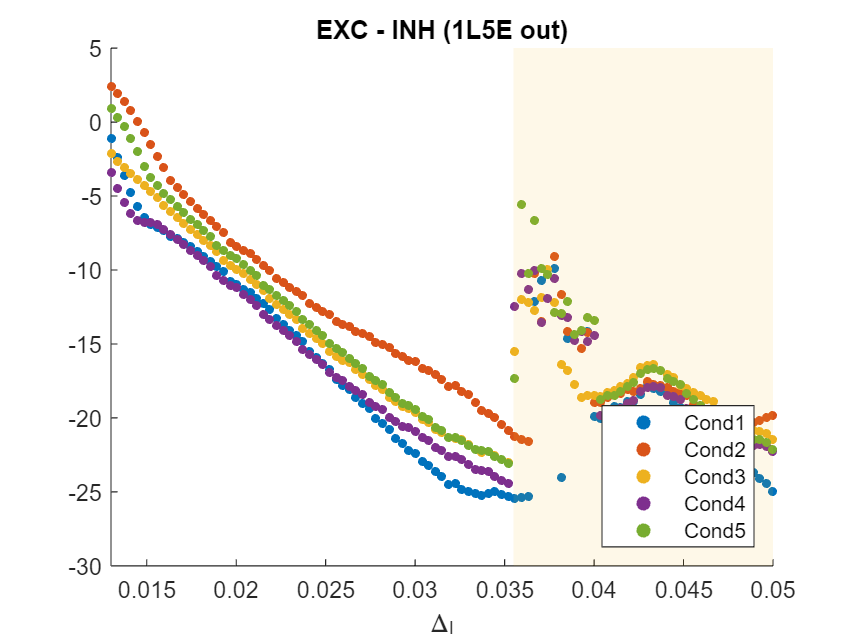

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
% lowY = 55; highY = 95;
sz = 15; pop = 5;
x = linspace(startX,endX,size(PET,1));
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); % + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
s = zeros(5,1);
figure();
for i = 1:5
    out = exc(:,i) - inh(:,i);
    s(i) = scatter(x, out, sz, 'filled');
    hold on
end

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);
% 
% recX = [0.036 0.05 0.05 0.036];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);
% xline(0.032, 'LineWidth', 1.5);
% xline(0.0355, 'LineWidth', 1.5);
labels = {'Cond1', 'Cond2', 'Cond3', 'Cond4', 'Cond5'};
legend(s,labels,'Location','southeast');
title("EXC - INH (1L5E out)");
axis([startX endX -30 5]);
xlabel("\Delta_{I}");

## Delta_i: EXC + INH, 1L5E in

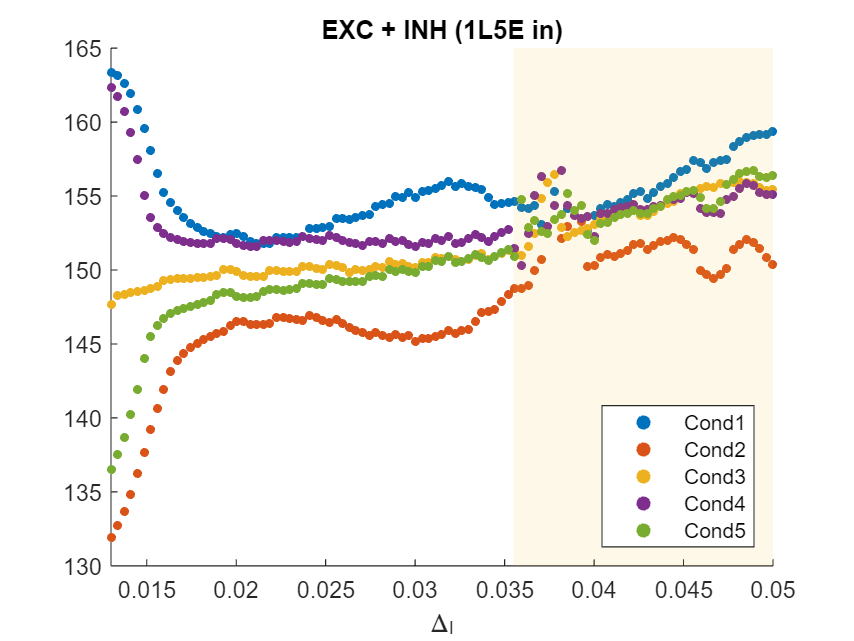

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
% lowY = 55; highY = 95;
sz = 15; pop = 5;
x = linspace(startX,endX,size(PET,1));
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
s = zeros(5,1);
figure();
for i = 1:5
    out = exc(:,i) + inh(:,i);
    s(i) = scatter(x, out, sz, 'filled');
    hold on
end

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);
% 
% recX = [0.036 0.05 0.05 0.036];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);
% xline(0.032, 'LineWidth', 1.5);
% xline(0.0355, 'LineWidth', 1.5);
labels = {'Cond1', 'Cond2', 'Cond3', 'Cond4', 'Cond5'};
legend(s,labels,'Location','southeast');
title("EXC + INH (1L5E in)");
axis([startX endX 130 165]);
xlabel("\Delta_{I}");

## Delta_i: EXC + INH, 1L5E out

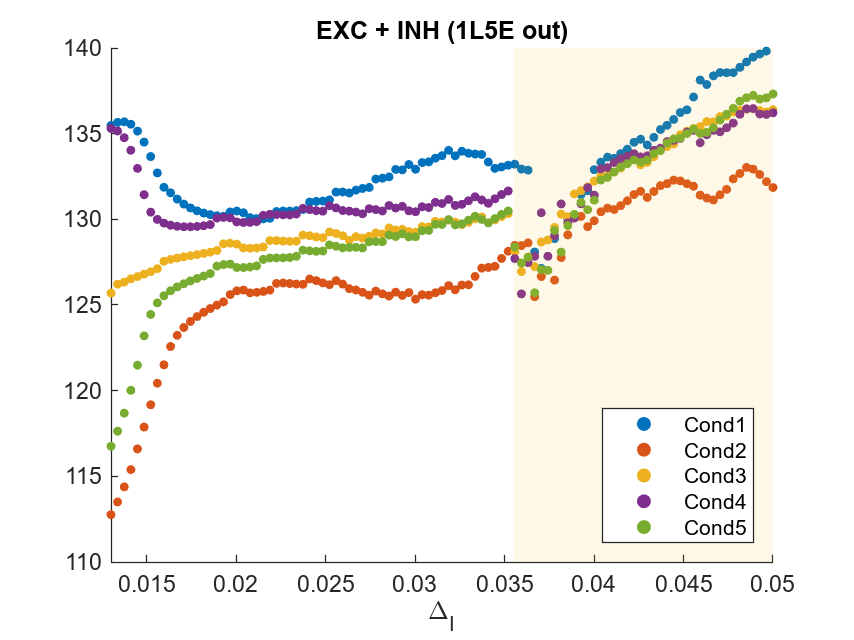

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
% lowY = 55; highY = 95;
sz = 15; pop = 5;
x = linspace(startX,endX,size(PET,1));
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); % + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
s = zeros(5,1);
figure();
for i = 1:5
    out = exc(:,i) + inh(:,i);
    s(i) = scatter(x, out, sz, 'filled');
    hold on
end

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);
% 
% recX = [0.036 0.05 0.05 0.036];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);
% xline(0.032, 'LineWidth', 1.5);
% xline(0.0355, 'LineWidth', 1.5);
labels = {'Cond1', 'Cond2', 'Cond3', 'Cond4', 'Cond5'};
legend(s,labels,'Location','southeast');
title("EXC + INH (1L5E out)");
axis([startX endX 110 140]);
xlabel("\Delta_{I}");

## Delta_i: contribution of pathway

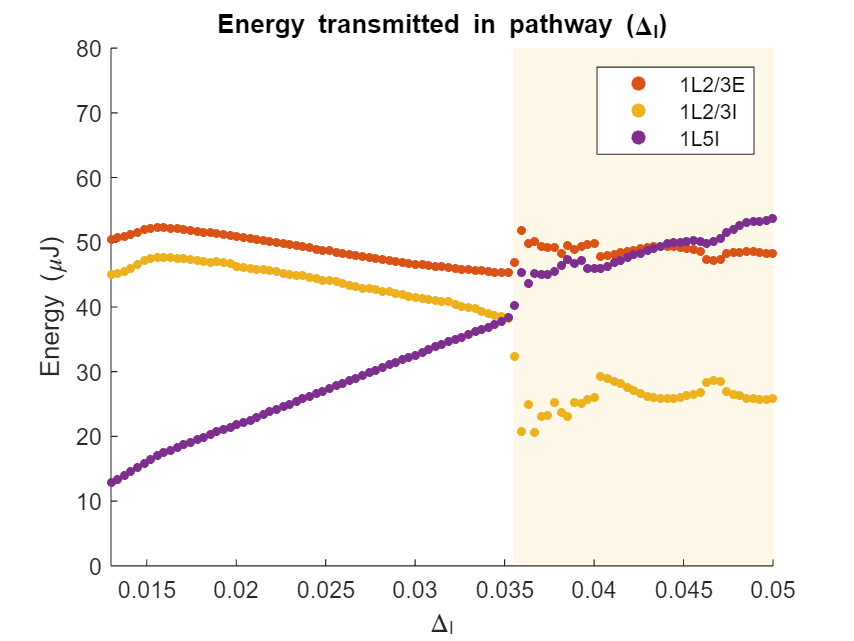

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
lowY = 0; highY = 80; % 80
cond = 5;
x = linspace(startX,endX,size(PET,1));
figure();
hold on;

recX = [0.0355 0.05 0.05 0.0355];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);


y1 = PET(:,pop,1,cond); y2 = PET(:,pop,2,cond); y3 = PET(:,pop,6,cond);
s1 = scatter(x,y1,sz,'filled','LineWidth',2);
hold on;
s2 = scatter(x,y2,sz,'filled','LineWidth',2);
s3 = scatter(x,y3,sz,'filled','LineWidth',2);
legend([s1 s2 s3],["1L2/3E", "1L2/3I", "1L5I"]);
xlabel("\Delta_{I}");
ylabel("Energy (\muJ)");
title("Energy transmitted in pathway (\Delta_{I})");
axis([startX endX lowY highY]);

## Delta_i: Pick key pathways

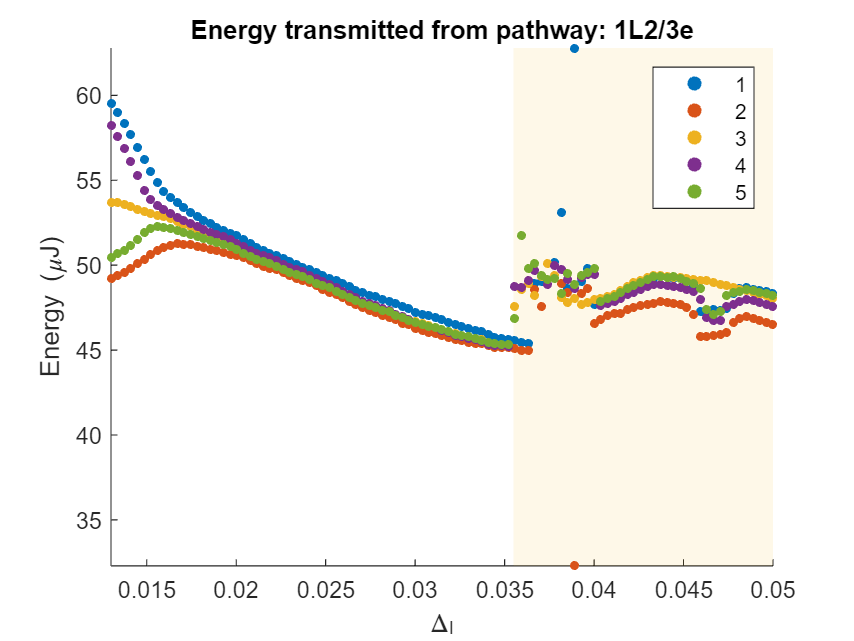

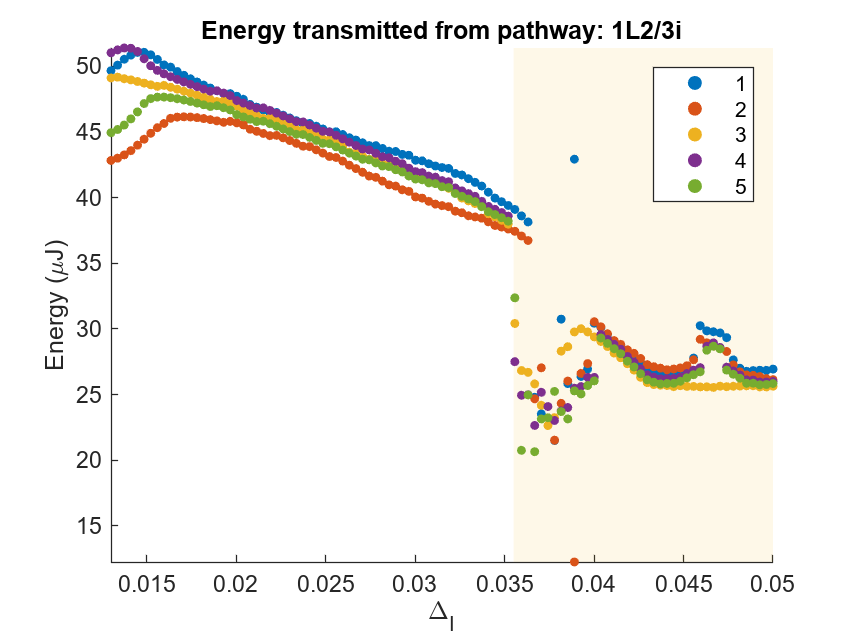

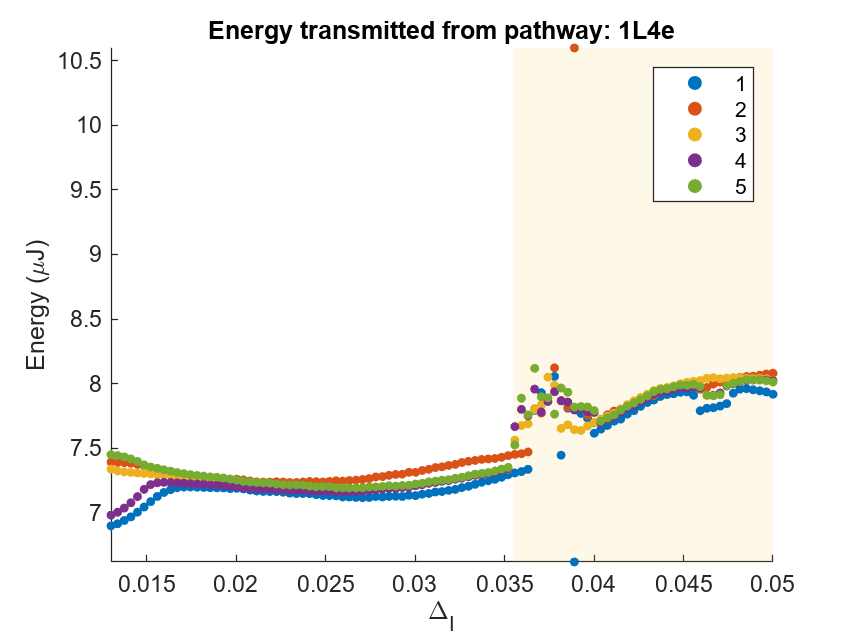

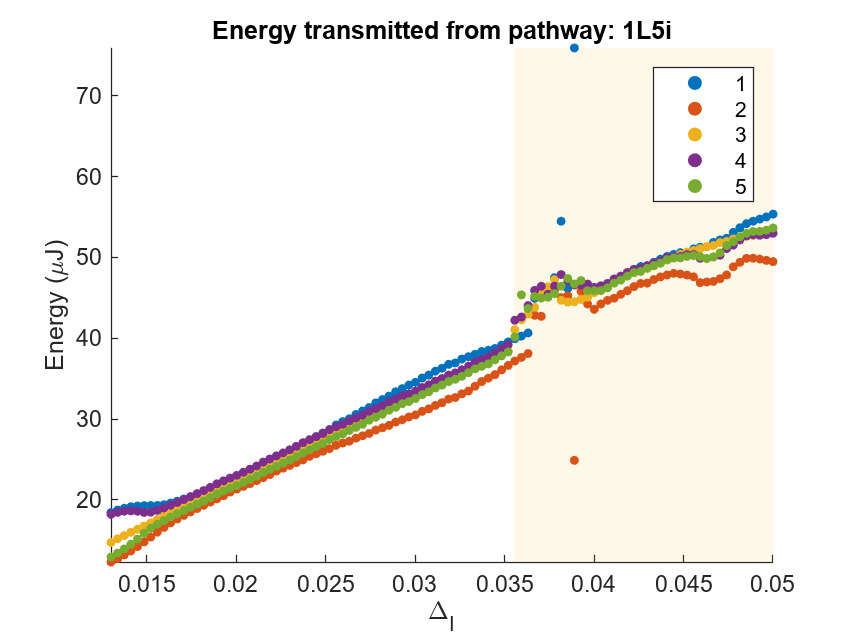

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05; pop = 5; sz = 15;
axlabels = {'1L2/3e','1L2/3i','1L4e','1L4i','1L5e','1L5i','1L6e','1L6i', ...
    '2L2/3e','2L2/3i','2L4e','2L4i','2L5e','2L5i','2L6e','2L6i'};
lowY = 44; highY = 60; % 80
x = linspace(startX,endX,size(PET,1));

for i = [1 2 3 6]
    s = zeros(5,1);
    figure();
    hold on;

    recX = [0.0355 0.05 0.05 0.0355];
    recY = [-200 -200 200 200];
    r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
    alpha(r1,0.1);

    cond1 = PET(:,pop,i,1); cond2 = PET(:,pop,i,2); cond3 = PET(:,pop,i,3);
    cond4 = PET(:,pop,i,4); cond5 = PET(:,pop,i,5); 
    s(1) = scatter(x,cond1,sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,cond2,sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,cond3,sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,cond4,sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,cond5,sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"]);
    xlabel("\Delta_{I}");
    ylabel("Energy (\muJ)");
    title("Energy transmitted from pathway: "+axlabels(i));
    axis([startX endX min(min(PET(:,pop,i,:))) max(max(PET(:,pop,i,:)))]);
end


% axis([startX endX lowY highY]);


## Delta_i: Consider both pathway in and out

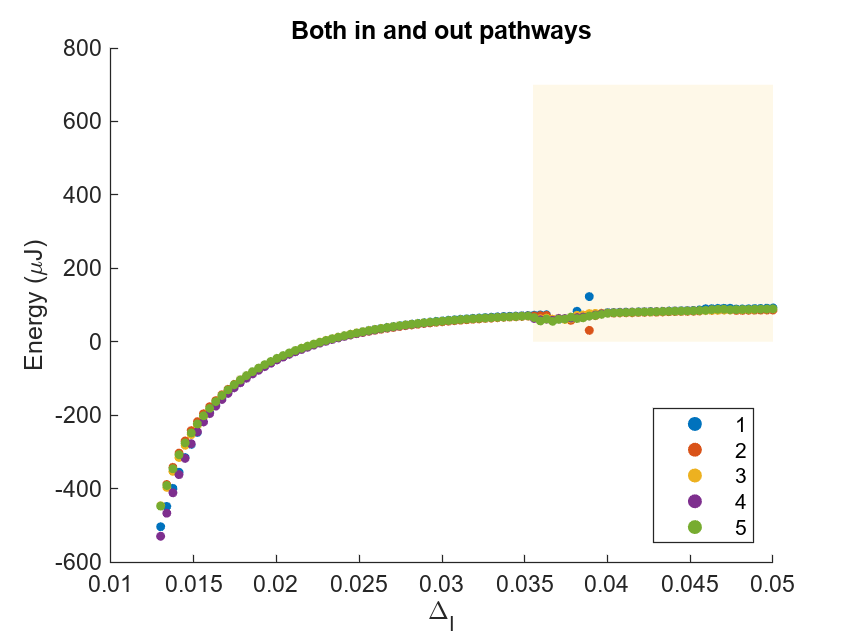

% (EXC_in - INH_in) - ALL_out
load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05; pop = 5;
x = linspace(startX,endX,size(PET,1));
excIn = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inhIn = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
allOut = squeeze(sum(squeeze(PET(:,:,pop,:)),2));
y =  (excIn + inhIn) - allOut;
figure();

hold on;
recX = [0.0355 0.05 0.05 0.0355];
recY = [0 0 700 700];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

s = zeros(5,1);
s(1) = scatter(x,y(:,1),sz,"filled",'MarkerFaceColor','#0072BD');
s(2) = scatter(x,y(:,2),sz,"filled",'MarkerFaceColor','#D95319');
s(3) = scatter(x,y(:,3),sz,"filled",'MarkerFaceColor','#EDB120');
s(4) = scatter(x,y(:,4),sz,"filled",'MarkerFaceColor','#7E2F8E');
s(5) = scatter(x,y(:,5),sz,"filled",'MarkerFaceColor','#77AC30');
legend(s,["1","2","3","4","5"],'Location','southeast');
xlabel("\Delta_{I}");
ylabel("Energy (\muJ)");
title("Both in and out pathways");

% axis([startX endX 50 150]);


## Delta_e: all pathway raw data

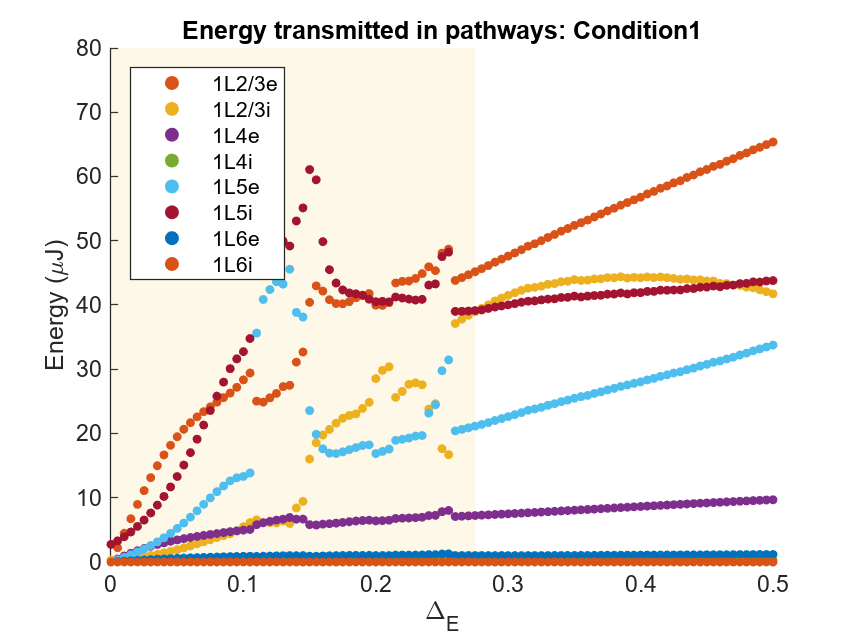

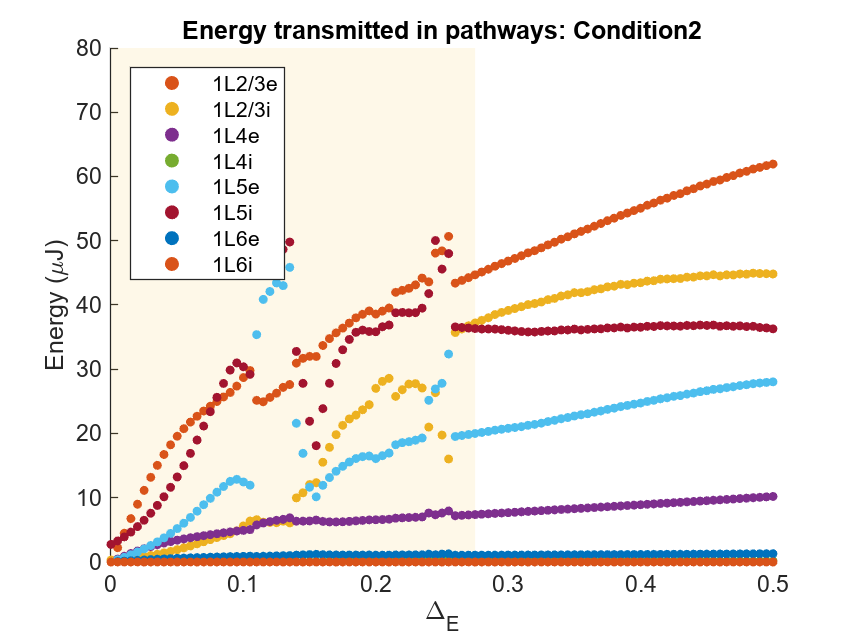

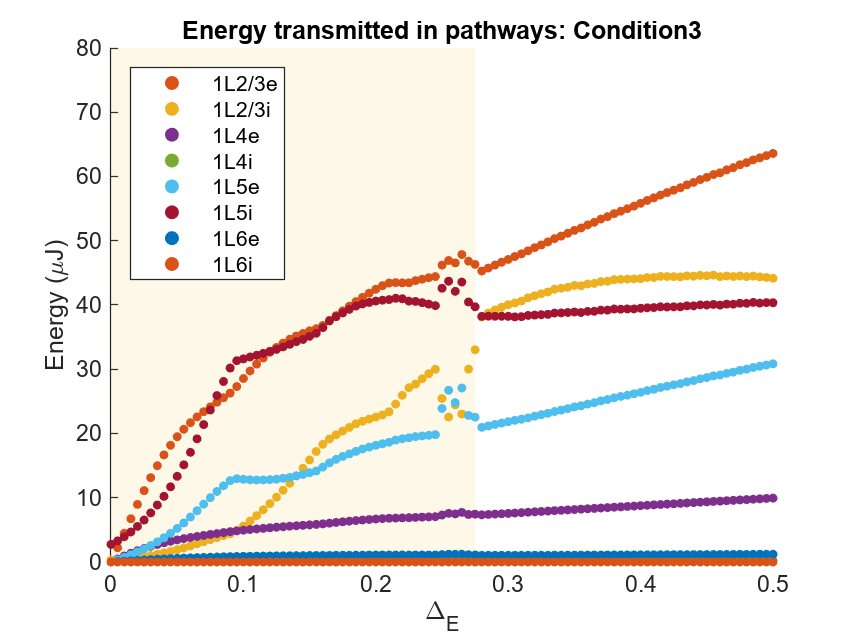

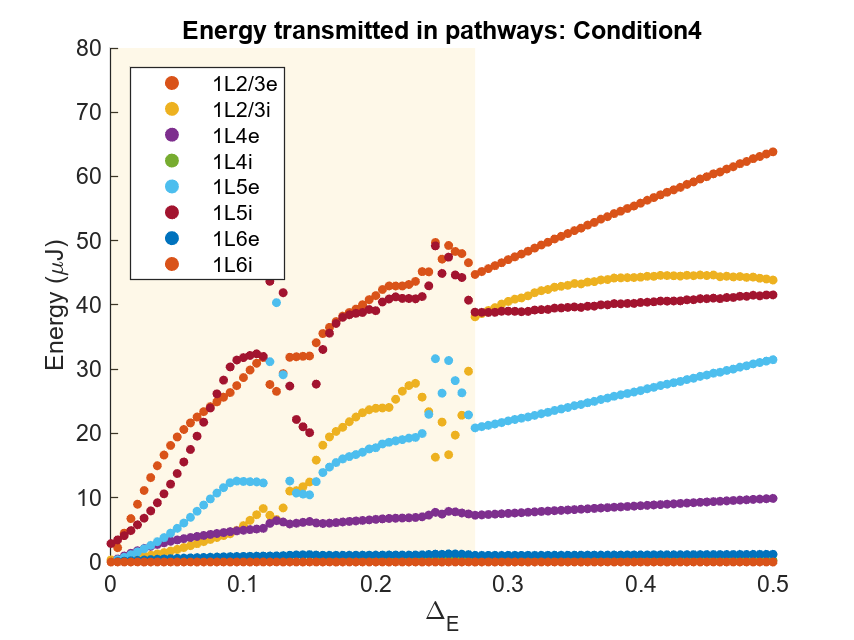

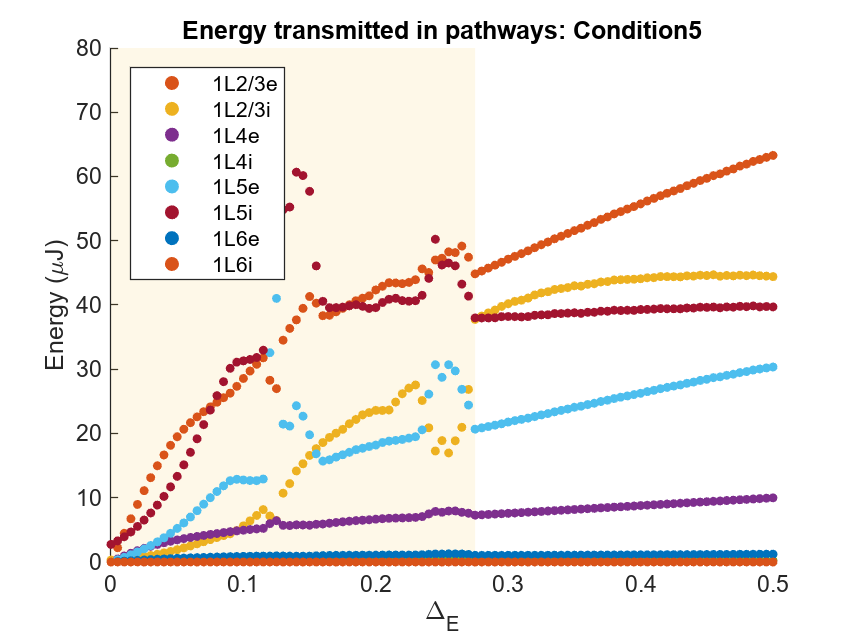

load data/0_0.5_0.035_0.035_Iattn_0.02.mat;
startX = 0; endX = 0.5;
lowY = 0; highY = 80; % 80
x = linspace(startX,endX,size(PET,1));

for cond = 1:5
figure();
hold on;
recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

% recX = [0.036 0.05 0.05 0.036];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);

s = zeros(8,1);
for i = 1:8
    y = PET(:,pop,i,cond);
    s(i) = scatter(x,y,sz,'filled','LineWidth',2);
    hold on;
end

legend(s,axlabels(1:8),'Location','northwest');
xlabel("\Delta_{E}");
ylabel("Energy (\muJ)");
title("Energy transmitted in pathways: Condition" + num2str(cond));
axis([startX endX lowY highY]);
end

## Delta_e: sum all excitatory or inhibitory effect

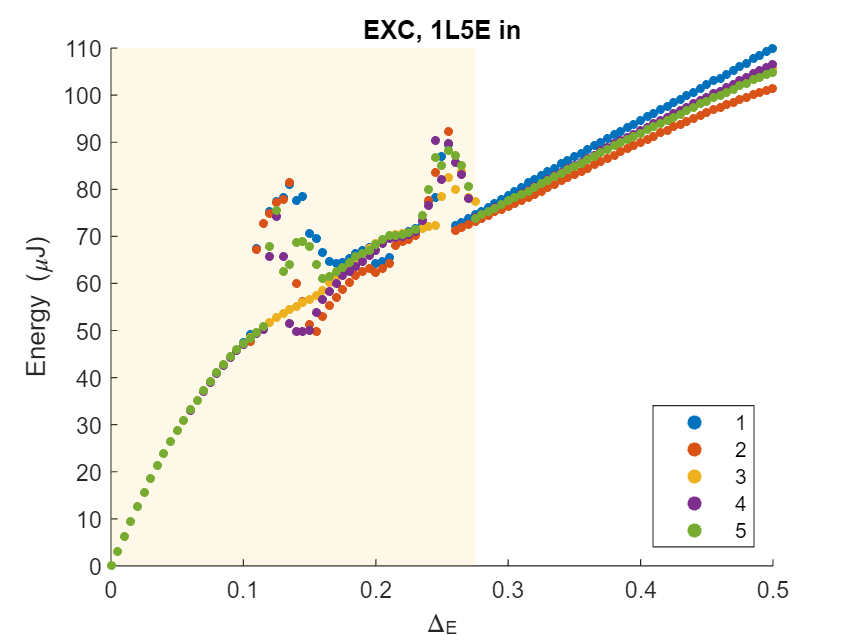

exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
lowY = 0; highY = 120;
% EXC, 1L5E in
figure();
hold on;
recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

s = zeros(5,1);
    s(1) = scatter(x,exc(:,1),sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,exc(:,2),sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,exc(:,3),sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,exc(:,4),sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,exc(:,5),sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"],'Location','southeast');
xlabel("\Delta_{E}");
ylabel("Energy (\muJ)");
title("EXC, 1L5E in");

axis([startX endX 0 110]);

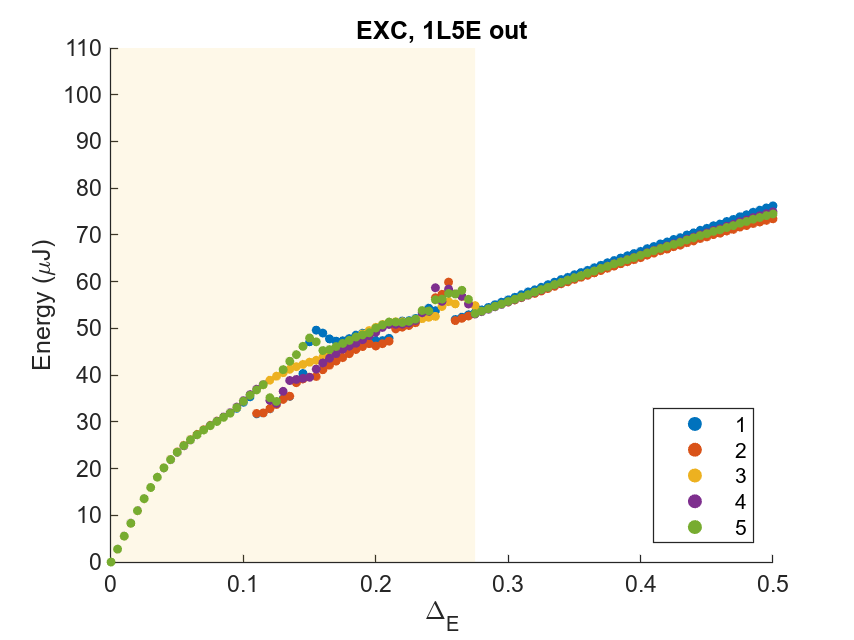


% EXC, 1L5E out
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); % + squeeze(PET(:,pop,7,:));
figure();
hold on;
recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

s = zeros(5,1);
    s(1) = scatter(x,exc(:,1),sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,exc(:,2),sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,exc(:,3),sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,exc(:,4),sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,exc(:,5),sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"],'Location','southeast');
xlabel("\Delta_{E}");
ylabel("Energy (\muJ)");
title("EXC, 1L5E out");

axis([startX endX 0 110]);

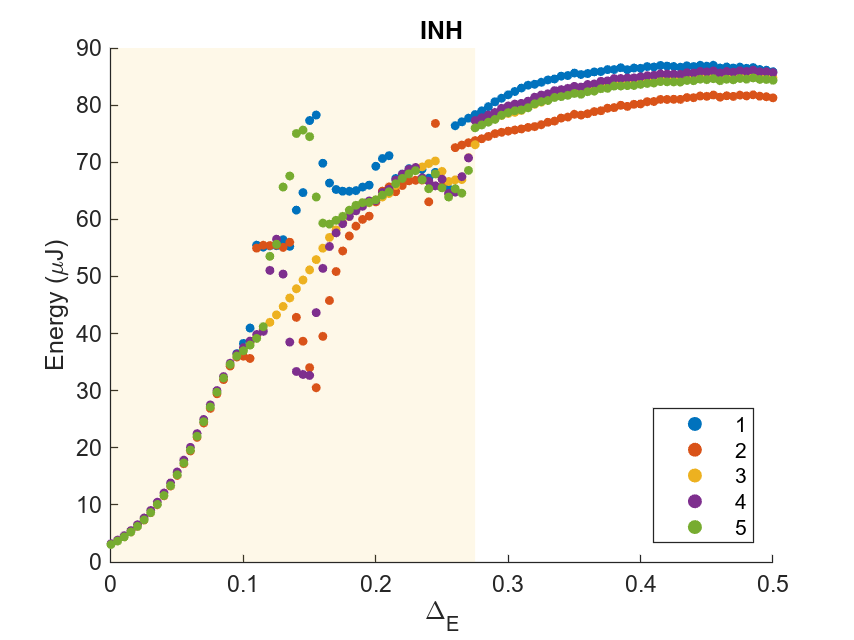


% INH
figure();
hold on;
recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

s = zeros(5,1);
    s(1) = scatter(x,inh(:,1),sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,inh(:,2),sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,inh(:,3),sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,inh(:,4),sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,inh(:,5),sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"],'Location','southeast');
xlabel("\Delta_{E}");
ylabel("Energy (\muJ)");
title("INH");

axis([startX endX 0 90]);

## Delta_e: EXC-INH (1L5E out)

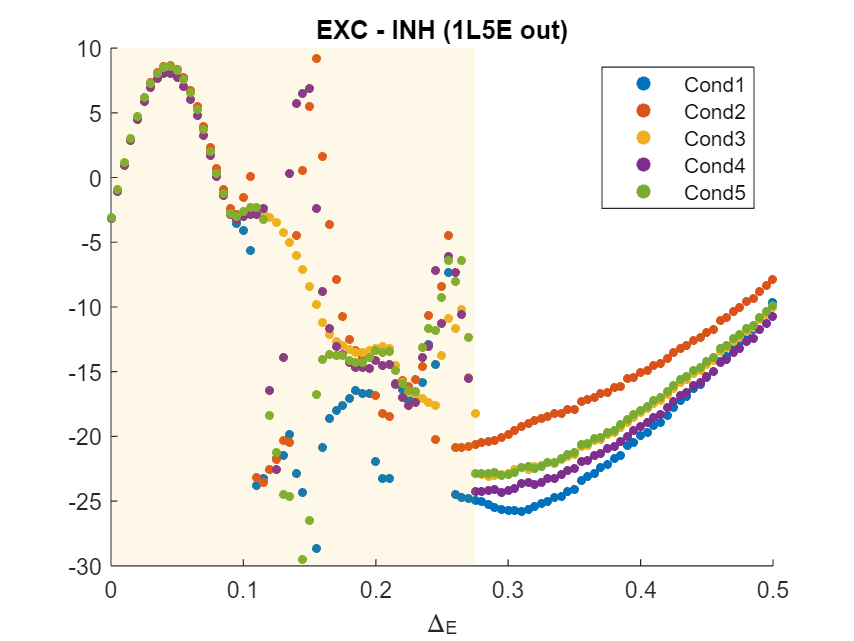

load data/0_0.5_0.035_0.035_Iattn_0.02.mat;
startX = 0; endX = 0.5;
% lowY = 55; highY = 95;
sz = 15; pop = 5;
x = linspace(startX,endX,size(PET,1));
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); % + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
s = zeros(5,1);
figure();
for i = 1:5
    out = exc(:,i) - inh(:,i);
    s(i) = scatter(x, out, sz, 'filled');
    hold on
end

recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

labels = {'Cond1', 'Cond2', 'Cond3', 'Cond4', 'Cond5'};
legend(s,labels,'Location','northeast');
title("EXC - INH (1L5E out)");
axis([startX endX -30 10]);
xlabel("\Delta_{E}");

## Delta_e: EXC+INH (1L5E in)

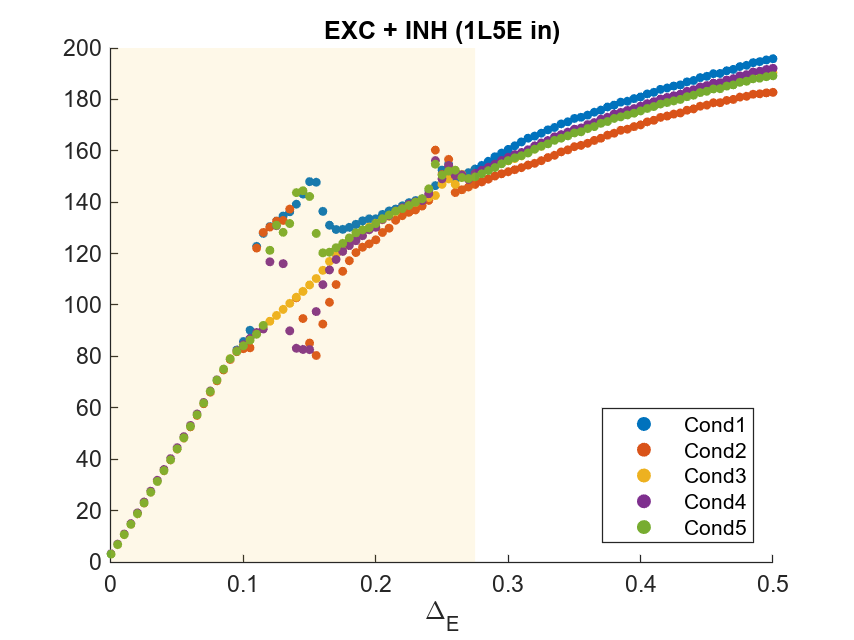

load data/0_0.5_0.035_0.035_Iattn_0.02.mat;
startX = 0; endX = 0.5;
% lowY = 55; highY = 95;
sz = 15; pop = 5;
x = linspace(startX,endX,size(PET,1));
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,5,:)) + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
s = zeros(5,1);
figure();
for i = 1:5
    out = exc(:,i) + inh(:,i);
    s(i) = scatter(x, out, sz, 'filled');
    hold on
end

recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

% recX = [0.036 0.05 0.05 0.036];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);
% xline(0.275, 'LineWidth', 1.5);
% xline(0.0355, 'LineWidth', 1.5);
labels = {'Cond1', 'Cond2', 'Cond3', 'Cond4', 'Cond5'};
legend(s,labels,'Location','southeast');
axis([startX endX 0 200]);
xlabel("\Delta_{E}");
title("EXC + INH (1L5E in)");

## Delta_e: EXC+INH (1L5E out)

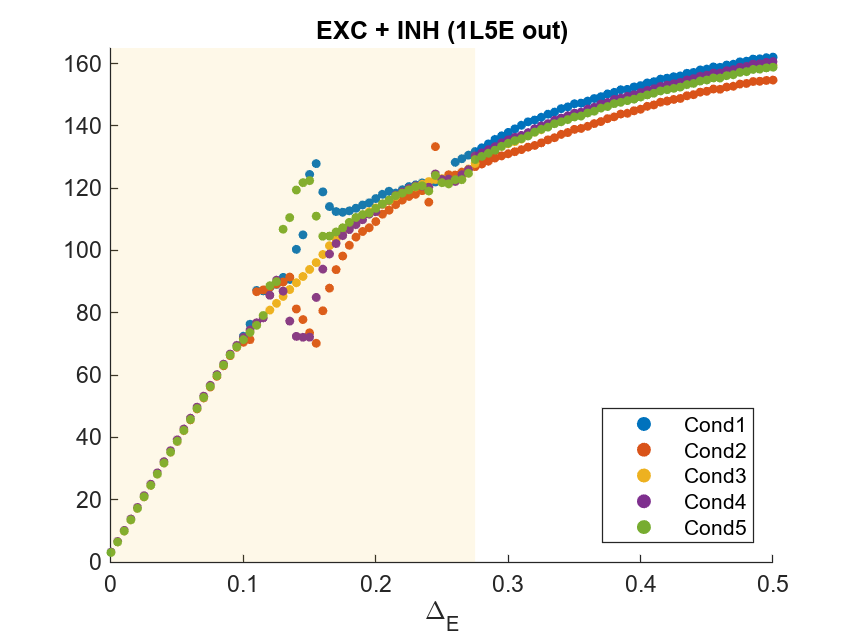

load data/0_0.5_0.035_0.035_Iattn_0.02.mat;
startX = 0; endX = 0.5;
% lowY = 55; highY = 95;
sz = 15; pop = 5;
x = linspace(startX,endX,size(PET,1));
exc = squeeze(PET(:,pop,1,:)) + squeeze(PET(:,pop,3,:)) + ...
    squeeze(PET(:,pop,7,:)); % + squeeze(PET(:,pop,7,:));
inh = squeeze(PET(:,pop,2,:)) + squeeze(PET(:,pop,4,:)) + ...
    squeeze(PET(:,pop,6,:)) + squeeze(PET(:,pop,8,:));
s = zeros(5,1);
figure();
for i = 1:5
    out = exc(:,i) + inh(:,i);
    s(i) = scatter(x, out, sz, 'filled');
    hold on
end

recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

% recX = [0.036 0.05 0.05 0.036];
% recY = [lowY lowY highY highY];
% r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
% alpha(r2,0.1);
% xline(0.275, 'LineWidth', 1.5);
% xline(0.0355, 'LineWidth', 1.5);
labels = {'Cond1', 'Cond2', 'Cond3', 'Cond4', 'Cond5'};
legend(s,labels,'Location','southeast');
axis([startX endX 0 165]);
xlabel("\Delta_{E}");
title("EXC + INH (1L5E out)");

## Delta_e: Pick key pathways

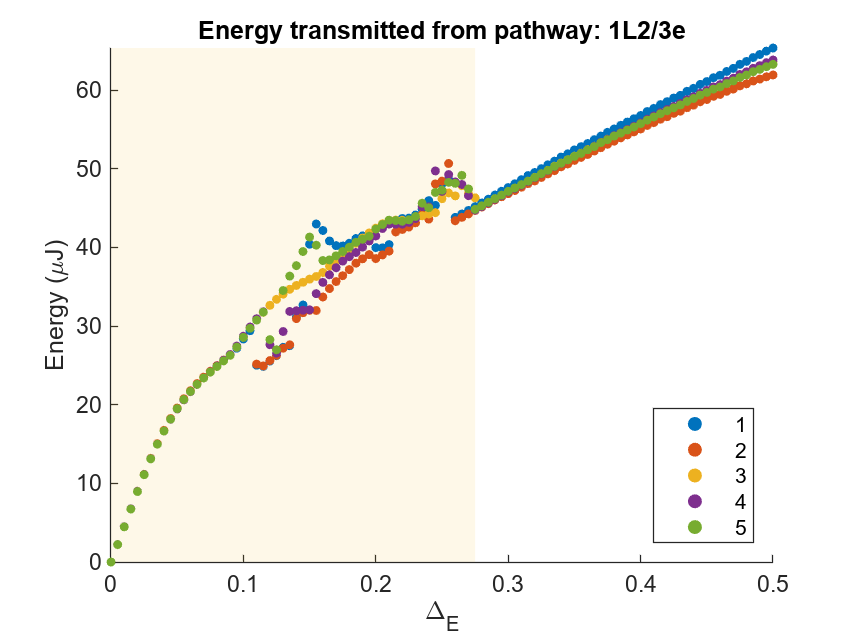

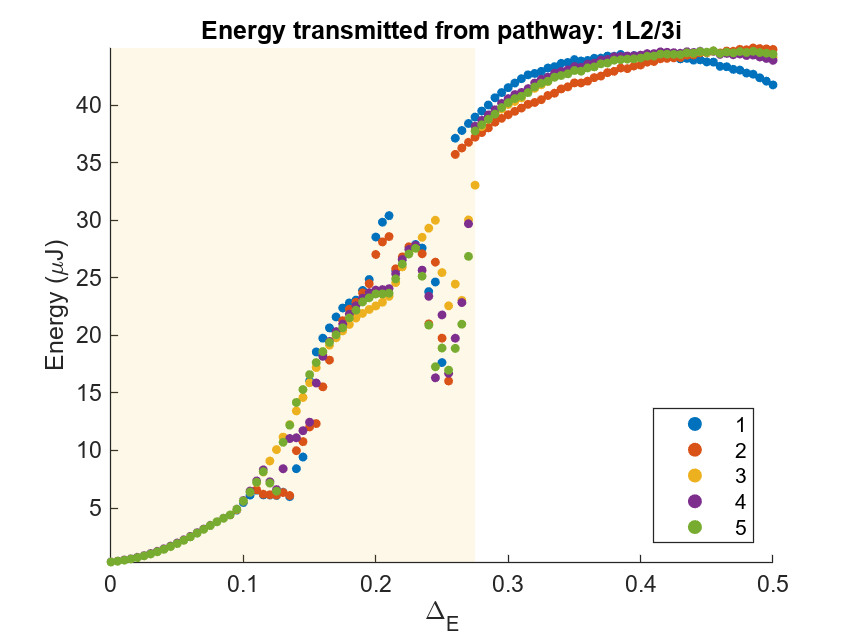

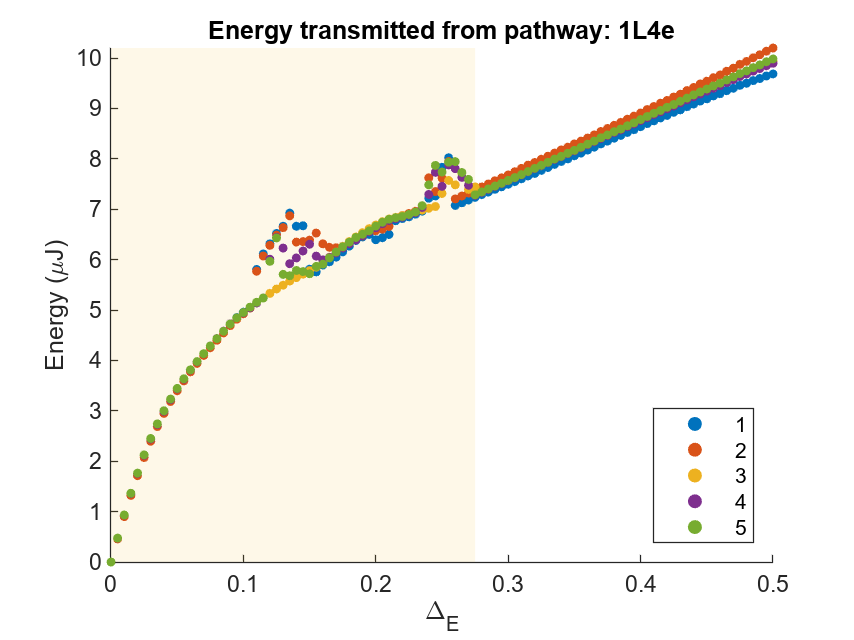

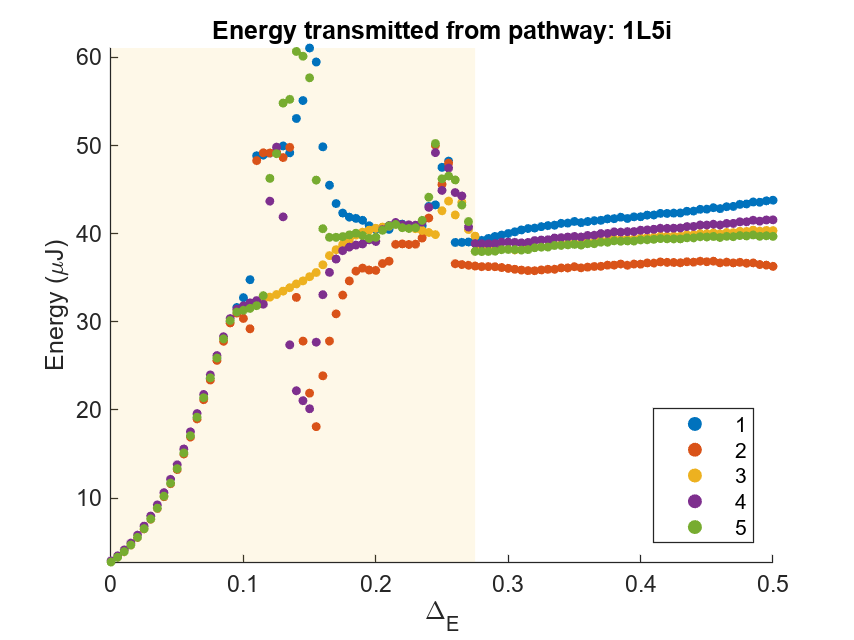

load data/0_0.5_0.035_0.035_Iattn_0.02.mat;
startX = 0; endX = 0.5;
x = linspace(startX,endX,size(PET,1));

for i = [1 2 3 6]
    s = zeros(5,1);
    figure();
    hold on;

recX = [0 0.275 0.275 0];
recY = [-200 -200 200 200];
r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
alpha(r1,0.1);

    cond1 = PET(:,pop,i,1); cond2 = PET(:,pop,i,2); cond3 = PET(:,pop,i,3);
    cond4 = PET(:,pop,i,4); cond5 = PET(:,pop,i,5); 
    s(1) = scatter(x,cond1,sz,"filled",'MarkerFaceColor','#0072BD');
    s(2) = scatter(x,cond2,sz,"filled",'MarkerFaceColor','#D95319');
    s(3) = scatter(x,cond3,sz,"filled",'MarkerFaceColor','#EDB120');
    s(4) = scatter(x,cond4,sz,"filled",'MarkerFaceColor','#7E2F8E');
    s(5) = scatter(x,cond5,sz,"filled",'MarkerFaceColor','#77AC30');
    legend(s,["1","2","3","4","5"],'Location','southeast');
    xlabel("\Delta_{E}");
    ylabel("Energy (\muJ)");
    title("Energy transmitted from pathway: "+axlabels(i));
    axis([startX endX min(min(PET(:,pop,i,:))) max(max(PET(:,pop,i,:)))]);
end


% axis([startX endX lowY highY]);


## f-I curve (r-I curve)

## function

function out = Fei(exc,inh)
    out = exc - inh;
end